We compute shooting solutions for several values of $\lambda$.

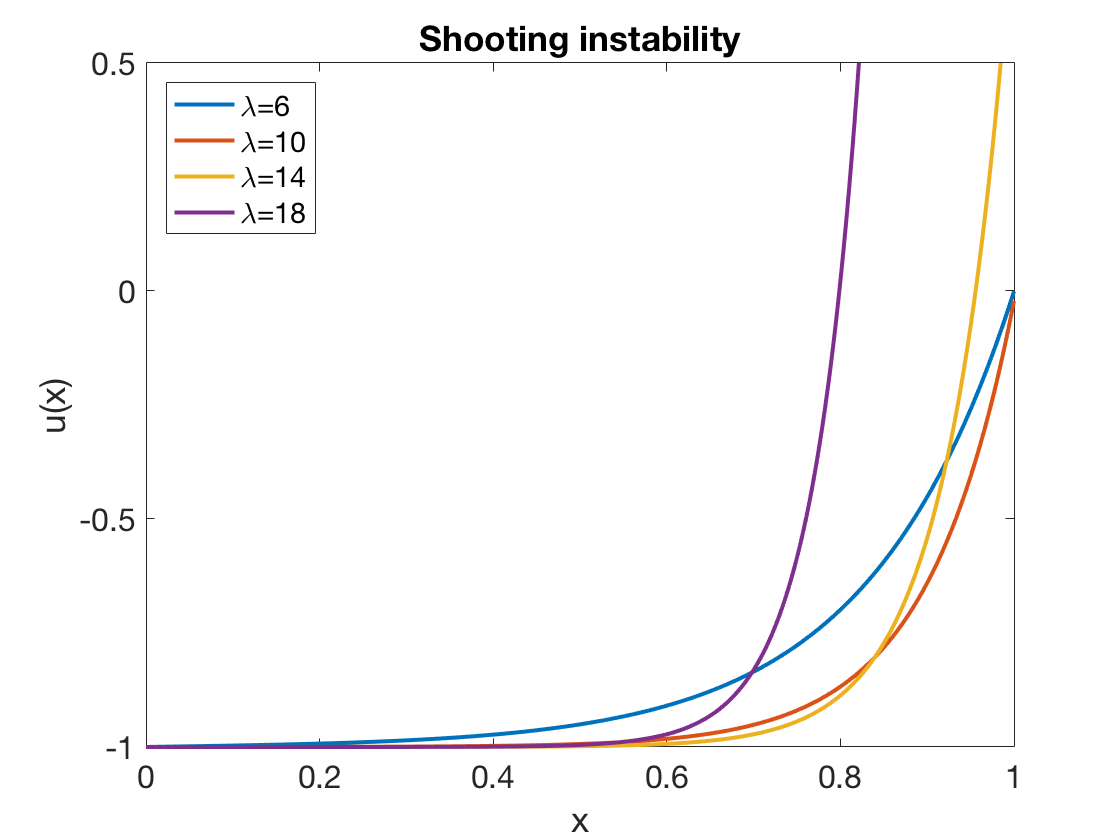

lambda = (6:4:18)';
for k = 1:4
    lam = lambda(k);
    lval = -1;  rval = 0;
    phi = @(x,u,dudx) lam^2*u + lam^2;
    [x,u] = shoot(phi,[0,1],lval,[],rval,[],0);

    plot(x,u,'-'), hold on
    
    xlabel('x'), ylabel('u(x)'),  ylim([-1 0.5])   % ignore this line
    title('Shooting instability')    % ignore this line
end
lstr = {'\lambda=6','\lambda=10','\lambda=14','\lambda=18'};    % ignore this line
legend(lstr,'location','northwest')   % ignore this line

The solutions do not stay negative on the right half of the domain as $\lambda$ increases.